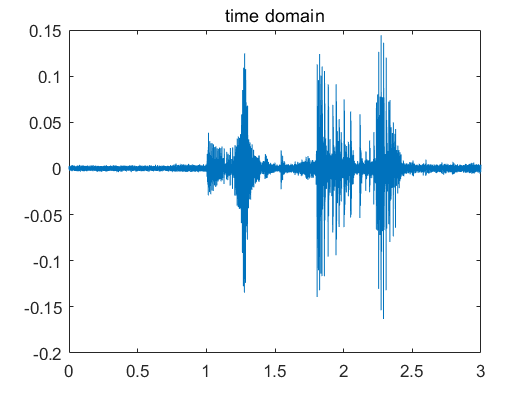

%(1)Load file
load('Q2\human_voice.mat');

%(2)load the waveform and plot it in the time domain
t1=0:1/Fs:3;t1=t1(1:end-1);
plot(t1,xs_noised);title("time domain");


%(3)
soundsc(xs_noised,Fs);%use soundsc to play
pause(3.5);%use pause command to block the execution until the sound is played over
%identify the time range of the announced characters
disp("the time range of 你 is 1s to 1.5s");%use disp command to annouce the time range

the time range of 你 is 1s to 1.5s


disp("the time range of 好 is 1.6s to 2.5s");

the time range of 好 is 1.6s to 2.5s


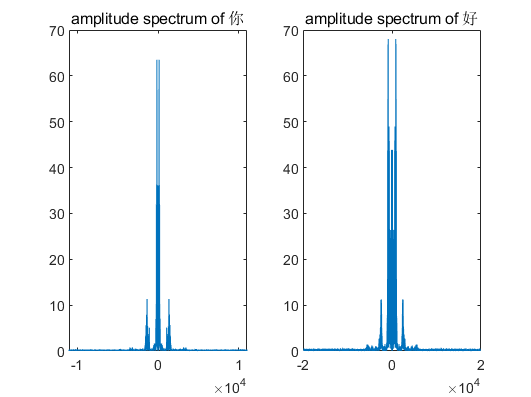


%(4)plot the amplitude spectrum of each character in the frequency domain
ni=xs_noised(44100:66150);%the frequency is 44100,so 1s is 44100, 1.5s is 66150
hao=xs_noised(70560:110250);%1.6s is 70560, 2.5s is 110250
ni_Y=fft(ni);
hao_Y=fft(hao);

t2=0:1/Fs:0.5;
t3=0:1/Fs:0.9;
t4=(-11025:11025);
t5=(-19845:19845);
figure
subplot(1,2,1);plot(t4,abs(fftshift(ni_Y)));title("amplitude spectrum of 你");
subplot(1,2,2);plot(t5,abs(fftshift(hao_Y)));title("amplitude spectrum of 好");

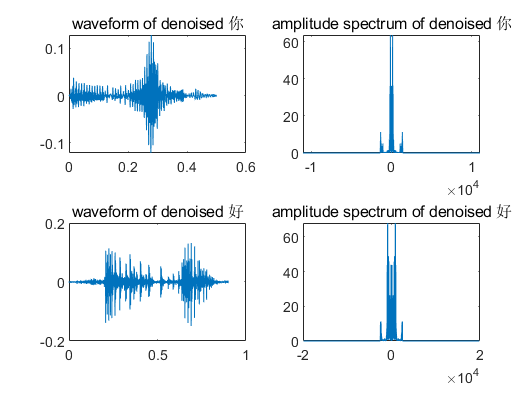


%(5)denoise the signal use FFT per character
ni_Y(1400:20650)=0;
ni_denoised=ifft(ni_Y);%denoise 你
hao_Y(2500:37190)=0;
hao_denoised=ifft(hao_Y);%denoise 好

figure
subplot(2,2,1);plot(t2,real(ni_denoised));title("waveform of denoised 你");
subplot(2,2,2);plot(t4,abs(fftshift(ni_Y)));title("amplitude spectrum of denoised 你");
subplot(2,2,3);plot(t3,real(hao_denoised));title("waveform of denoised 好");
subplot(2,2,4);plot(t5,abs(fftshift(hao_Y)));title("amplitude spectrum of denoised 好");

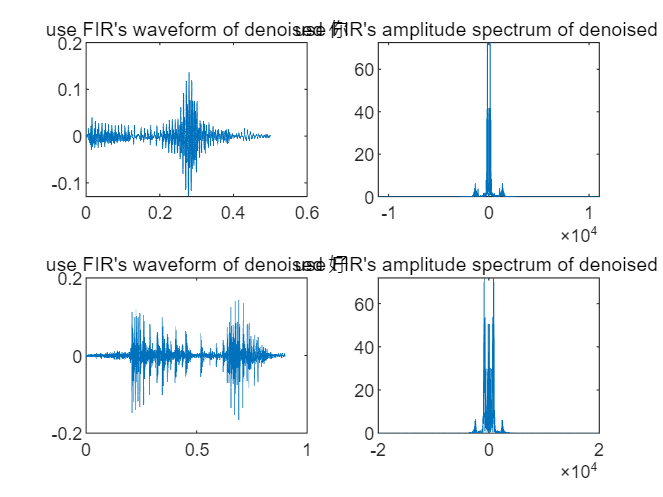


soundsc(real(ni_denoised),Fs);%use soundsc to play the denoised signal of 你
pause(1.0);%pause more than 0.5s
soundsc(real(hao_denoised),Fs);%use soundsc to play the denoised signal of 好
pause(1.5);%pause more than 0.9s

%(6)Filter the signal use with FIR per character
f_ni=filter(my_filterni,ni);
y_ni=fft(f_ni);
f_hao=filter(my_filterhao,hao);
y_hao=fft(f_hao);

soundsc(f_ni,Fs);%use soundsc to play the FIR's denoised signal of 你
pause(1.0);
soundsc(f_hao,Fs);%use soundsc to play the FIR's denoised signal of 好
pause(1.5);

figure
subplot(2,2,1);plot(t2,f_ni);title("use FIR's waveform of denoised 你");
subplot(2,2,2);plot(t4,abs(fftshift(y_ni)));title("use FIR's amplitude spectrum of denoised 你");
subplot(2,2,3);plot(t3,f_hao);title("use FIR's waveform of denoised 好");
subplot(2,2,4);plot(t5,abs(fftshift(y_hao)));title("use FIR's amplitude spectrum of denoised 好");